data 불러오기 + skip frame 설정

load('st1.mat');

scans = scans(1:5:end);

맵 만들기

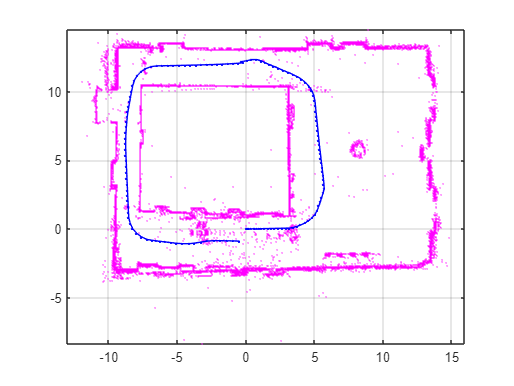

maxRange = 12; % meters
resolution = 20; % cells per meter

slamObj = lidarSLAM(resolution,maxRange);
slamObj.LoopClosureThreshold = 360;
slamObj.LoopClosureSearchRadius = 8;

for i = 1:numel(scans)

    addScan(slamObj,scans{i});
    
    if rem(i,10) == 0
        show(slamObj);
    end
end

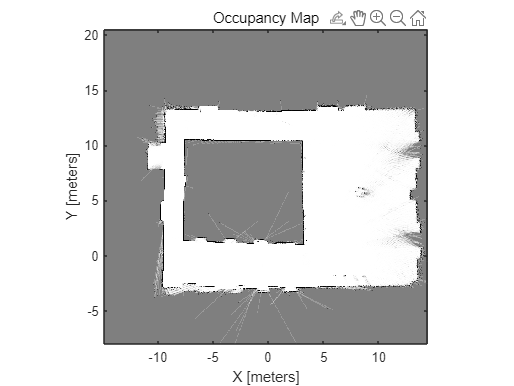


[scansSLAM,poses] = scansAndPoses(slamObj);
Map = buildMap(scansSLAM,poses,resolution,maxRange);
figure
show(Map)
title('Occupancy Map')